# Implementing a Multiclass Model With Code

The Classification Learner App is a helpful tool for interactively building and evaluating models. However, you may need to implement the model in code to access additional options that aren't available in the app. 

In this reading, you'll train the SVM model from the video "Training a Multiclass Model", which predicts the toll source from the taxi data. You'll also evaluate the model with class-specific metrics. Lastly, you'll customize the model with different options and compare the effects on the model performance.

## Prepare the data

Run this section of code to load the data and create the response variable `TollSource`. This variable contains a label with one of the six toll sources. 

taxi = importTaxiData("yellow_tripdata_2015-10.csv");
taxi = addTollSource(taxi);

Then remove the trips with no tolls since they are no longer needed. The size of the table becomes significantly smaller since many taxi trips have no toll.

taxi = filterTollTrips(taxi)

## Visualize class identities

The features you'll use to classify `TollSource` are the pickup and drop off locations. You can get an idea of which features will be helpful in the model by visualizing the labeled data points. 

Since these are geographic coordinates, it's helpful to use a geobubble plot. Run this section to see the distribution of pickup or dropoff locations superimposed on a map of New York City.

choice = "Dropoff";
geobubble(taxi,choice+"Lat",choice+"Lon", ...
    "ColorVariable","TollSource","BubbleWidthRange",5);
title(choice + " Locations")

## One vs. One Classification

You’ve learned that any binary classifier can be used for multiclass classification by training multiple models and leveraging them together. The strategy you learned previously was called "One vs. All" classification.

Another variant is called "One vs. One" classification. Here, a binary classification model is trained on each pair of classes. Consider the example below with three classes:

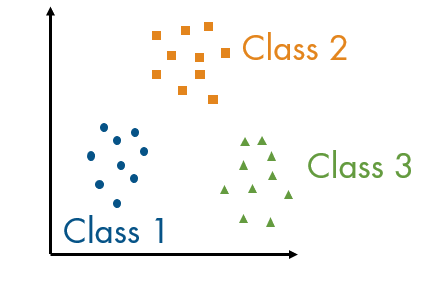

Three models will be trained using each pair of classes. In other words, each model uses a different subset of the data.

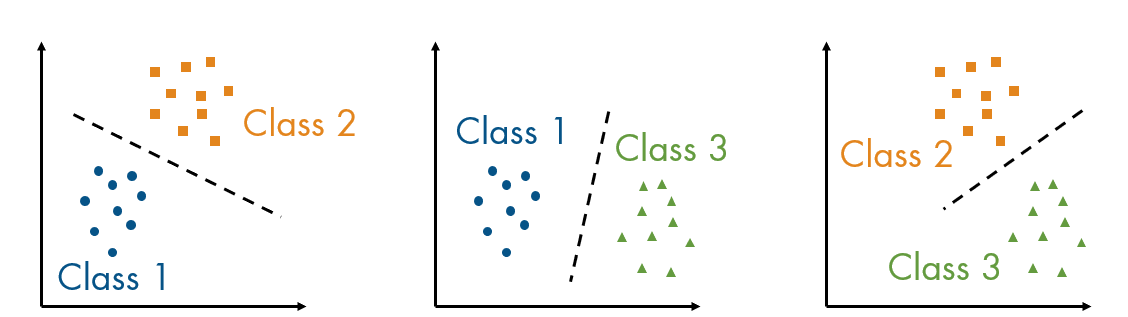

When predicting the class for a new datapoint, the binary predictions for each model are calculated, and the most commonly assigned class is chosen. 

In general, the One vs. One strategy will require a larger number of models than the One vs All strategy since a model is trained for each pair. For example, the `TollSource` variable has 6 classes, so there will be 15 models trained using the One vs One strategy. The One vs All strategy will train 6 models (one for each class). So which should you choose?

The performance of each strategy will depend on multiple factors like the number of observations and the number of classes. Try out multiple strategies and choose one that works well with your data.

## Train a multiclass model

The MATLAB function to train multiclass models is `fitcecoc`. The letters "ECOC" stand for "Error-Correcting Output Codes". You can read [the documentation](https://www.mathworks.com/help/stats/fitcecoc.html) for more information.

This function works similarly to the other classification functions like `fitcknn`, but there are a few unique options you need to specify.

- `"Learners"` allows you to set the type of model, such as `"svm"`, `"knn"`, or `"tree"`.

- `"Coding"` allows you to specify the strategy used, such as `"onevsall"` or `"onevsone"`. See the documentation for a description of all the available options.

mdl = fitcecoc(taxi,"TollSource", ...
    "PredictorNames",["PickupLat","PickupLon","DropoffLat","DropoffLon"], ...
    "Learners","svm", ...
    "Coding","onevsone")

## Evaluate a multiclass model

### Accuracy

Calculate the accuracy of the model by comparing the true classes with the predicted classes.

% Get the true and predicted classes
trueLabel = taxi.TollSource;
predictLabel = predict(mdl,taxi);

% Calculate the accuracy. Multiply by 100 to report the value as a
% percentage
sum(trueLabel==predictLabel)/length(trueLabel)*100

The accuracy will vary depending on your choice of model and multiclass strategy. However, given the class imbalance issue with this data (most datapoints belong to the "MTA" class), the accuracy will still be high. 

Try selecting the "svm" option above with "onevsall" coding. Then rerun this section. You should find the accuracy is around 97.7%, but this does not tell the full story. You need to look at the class-specific performance with the confusion matrix and metrics such as Recall and Fallout.

### Confusion matrix

The confusion matrix for a multiclass model will have a row and column for each class. In this case, that means a 6x6 matrix. You can look at the raw counts in the confusion matrix by setting "absolute" as the normalization option. If you prefer to get percentages, you can normalize the matrix either by row, column, or total count.

confusionchart(trueLabel,predictLabel,"Normalization","absolute");

You should see that most of the data points were predicted as the MTA class, which creates an overall high accuracy because of the class imbalance.

### Class-specific metrics

Metrics such as precision and recall can be calculated for each class using the counts in the confusion matrix. To help out, you've been provided with a custom function `cMetrics` that takes the labels as inputs and returns the class-specific metrics in a table.

cMetrics(trueLabel,predictLabel)

If you try the "svm" model with "onevsone" coding, you should see that the precision and recall for the MTA class are quite high (the recall will be exactly 1), but for the other classes they're very low or undefined.

For better performance, try the "tree" option, or continue on to the next section, where you'll customize the "svm" model to improve the performance.

## Customize a multiclass SVM model

To set model specific parameters, such as changing the kernel for an SVM model, create a template for the model you wish to use. Then, pass the template containing the various options to the `fitcecoc` function as the value for `"Learners"`. 

There are various template functions for the different types of models:

- `templateKNN`

- `templateSVM`

- `templateTree`

- `templateKernel`

- `templateLinear`

For example, the code below creates an SVM template that will standardize the predictors. This step is important in scale-sensitive models such as KNNs and SVMs, but not for other methods like classification trees or discriminant analysis models. 

You can try out different kernel functions as well, but to directly compare with the previous result, select the `"linear"` kernel, which is the default for `fitcecoc` with SVM learners.

template = templateSVM(...
    'KernelFunction', "linear", ...  
    'Standardize', true);

mdl = fitcecoc(taxi,"TollSource", ...
    "PredictorNames",["PickupLat","PickupLon","DropoffLat","DropoffLon"], ...
    "Learners",template, ...
    "Coding","onevsone")

## Evaluate the customized model

Let's predict the values for the customized model and look at the confusion matrix again. The accuracy is improved due to the standardization of the feature vectors because SVMs assume the features all have a similar scale.

% Get the true and predicted labels
trueLabel = taxi.TollSource;
predictLabel = predict(mdl,taxi);

% Calculate the accuracy
sum(trueLabel==predictLabel)/length(trueLabel)*100

Create a new confusion matrix to see how well the customized model predicts the various classes. When you select the "row-normalized" option, the values along the diagonal are the Recall (True Positive) rates, since the rows correspond to the true classes..

confusionchart(trueLabel,predictLabel,"Normalization","row-normalized");

Finally, calculate some class-specific metrics. Notice the significantly higher recall values for all but the "Other" class.

cMetrics(trueLabel,predictLabel)

## Next steps

The customized SVM model makes accurate predictions for every class except the "Other" class. You could try changing the model type or adding additional features to improve the model, but as mentioned previously, these toll amounts could have been recorded incorrectly. It's worth investigating the data further to see if they should be treated as missing data points. Nevertheless, you are now able to implement multiclass models in MATLAB with code.